# **Problema 3**

Se considera problem cu valori pe frontiera


$${y^{\prime } }^{\prime } =g\left(x,y,y^{\prime } \right),y\left(a\right)=\alpha ,y\left(b\right)=\beta \;\;\;\;\;\;\;\;\;\;\left(1\right)$$


(a) Ea poate fi discretizata notand $u_k =y\left(x_k \right)$ si inlocuid derivata intai si a doua prin formulele:


$$\begin{array}{l}
f^{\prime } \left(x\right)=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}+O\left(h^2 \right)\\
{f^{\prime } }^{\prime } \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }+O\left(h^2 \right)
\end{array}$$


relative la o grila de puncte echidistante $x_k =a+\frac{k}{n+1}h,k=0,1,\ldotp \ldotp \ldotp ,n,n+1,h=\frac{b-a}{n+1}$. Se ajunge la un sistem neliniar in necunoscutele $u_k ,k=1,\ldotp \ldotp \ldotp ,n$. Concepeti o metoda de rezolvare aproximativa a problemei (1) bazata pe metoda lui Newton.

### **Rezolvare**

Grila de noduri echidistante nu respecta formula standard $x_k =a+k\cdot h,k=0,1,\ldotp \ldotp \ldotp ,n,n+1,h=\frac{b-a}{n+1}$, care incapsuleaza o grila de $n+1$ noduri echidistante. Astfel, eroarea dintre 2 noduri succesive este:

$x_{k+1} -x_k =a+\frac{\left(k+1\right)\left(b-a\right)}{{\left(n+1\right)}^2 }-a-\frac{k\left(b-a\right)}{{\left(n+1\right)}^2 }=\frac{b-a}{{\left(n+1\right)}^2 }$, nodurile fiind tot echidistante, insa cu un pas exponential mai mic decat cel clasic. Prima derivata are deveni $y^{\prime } \left(x_k \right)\approx \frac{y\left(x_{k+1} \right)-y\left(x_{k-1} \right)}{2h^{\prime } },h^{\prime } =\frac{b-a}{{\left(n+1\right)}^2 }$, avand astfel o retea mult mai deasa deoarce $h^{\prime } <<h$, fiind numeric costisitor si care nu aduce beneficii evidente cand vine vorba de convergenta.

Din relatia nodurilor echidistante, rezulta formula: $x_k =a+k*\tilde{h} ,\tilde{h} =\frac{b-a}{{\left(n+1\right)}^2 }$, rezultand o grila de $n+2\;\textrm{noduri}\;\textrm{echidistante}\;\textrm{cu}\;\textrm{pas}\;\tilde{h}$.

Discretizam astfel functia necunoscuta, cu urmatoarele presupuneri:

- $u_k \approx y\left(x_k \right)$;

- conditiile de frontiera: $u_0 =\alpha ,u_{n+1} =\beta$;

Rezulta derivatele de ordin 1 si ordin 2:


$$\begin{array}{l}
y^{\prime } \left(x_k \right)\approx \frac{u_{k+1} -u_{k-1} }{2\tilde{h} }+O\left({\tilde{h} }^2 \right)\\
{y^{\prime } }^{\prime } \left(x_k \right)\approx \frac{u_{k+1} -2u_k +u_{k-1} }{{\tilde{h} }^2 }+O\left({\tilde{h} }^2 \right)
\end{array}$$


Astfel, problema de frontiera arata astfel in forma sa discretizata:


$$\frac{u_{k+1} -2u_k +u_{k-1} }{{\tilde{h} }^2 }=g\left(x_k ,u_k ,\frac{u_{k+1} -u_{k-1} }{2\tilde{h} }\right),u_0 =\alpha ,u_{n+1} =\beta ,\tilde{h} =\frac{b-a}{{\left(n+1\right)}^2 },k=1,\ldotp \ldotp \ldotp ,n$$


Rezulta astfel un sistem neliniar de ecuatii cu necunoscutele $u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
\ldotp \ldotp \ldotp \\
u_{n-1} \\
u_n 
\end{array}\right\rbrack$

Definim functia vectoriala$F_n \left(u\right)\in R^n ,F_k \left(u\right)=\frac{u_{k+1} -2u_k +u_{k-1} }{{\tilde{h} }^2 }-g\left(x_k ,u_{k,} \frac{u_{k+1} -u_{k-1} }{2\tilde{h} }\right),u_0 =\alpha ,u_{n+1} =\beta ,\tilde{h} =\frac{b-a}{{\left(n+1\right)}^2 },k=1,\ldotp \ldotp \ldotp ,n$

Rezulta astfel metoda:


$$u^{\left(m+1\right)} =u^{\left(m\right)} -J^{-1} \left(u^{\left(m\right)} \right)\cdot F\left(u^{\left(m\right)} \right),J_{\textrm{ij}} =\frac{\partial F_i }{\partial u_j }$$


#### Caz concret: n=3

Folosim metoda cu un caz concret avand 3 noduri. Fie problema:


$${y^{\prime } }^{\prime } =g\left(x,y,y^{\prime } \right)=y^{\prime } \left(y+1\right),y\left(0\right)=0,y\left(1\right)=1$$


Pasul $\tilde{h} =\frac{1-0}{{\left(3+1\right)}^2 }=\frac{1}{16}\Rightarrow x_0 =0,x_1 =\frac{1}{16},x_2 =\frac{2}{16},x_3 =\frac{3}{16},x_4 =\frac{1}{4}$

Cu necunoscutele: $u_0 =0,u_1 ,u_2 ,u_3 ,u_4 =1$.


$$\left\lbrace \begin{array}{ll}
F_1 =\frac{u_2 -2u_1 +u_0 }{{\tilde{h} }^2 }-\frac{u_2 -u_0 }{2\tilde{h} }\left(u_0 +1\right) & k=1\\
F_2 =\frac{u_3 -2u_2 +u_1 }{{\tilde{h} }^2 }-\frac{u_3 -u_1 }{2\tilde{h} }\left(u_2 +1\right) & k=2\\
F_3 =\frac{u_4 -2u_3 +u_2 }{{\tilde{h} }^2 }-\frac{u_3 -u_2 }{2\tilde{h} }\left(u_3 +1\right) & k=3
\end{array}\right.$$


Rezulta sistemul neliniar:


$$\begin{array}{l}
F_1 \left(u_1 ,u_2 \right)=\frac{u_2 -2u_1 +u_0 }{{\tilde{h} }^2 }-\frac{u_2 -u_0 }{2\tilde{h} }\left(u_1 +1\right)=0\\
F_2 \left(u_1 ,u_2 ,u_3 \right)=\frac{u_3 -2u_2 +u_1 }{{\tilde{h} }^2 }-\frac{u_3 -u_1 }{2\tilde{h} }\left(u_2 +1\right)=0\\
F_3 \left(u_2 ,u_3 \right)=\frac{u_4 -2u_3 +u_2 }{{\tilde{h} }^2 }-\frac{u_3 -u_2 }{2\tilde{h} }\left(u_3 +1\right)=0
\end{array}$$


Punctul (b) este implementat in MATLAB, mai jos.

% Numarul de noduri interne
n = 100;
% Domeniul de definitie
a = 0;
b = 1;
% Alpha, beta
alpha = 0;
beta = 1;
% Toleranta
tol = 0.5e-6;

% Noduri pentru verificare
x = linspace(a, b, n+2);

% Ours
U = solve_bvp_newton(n, a, b, alpha, beta, tol);

Convergenta atinsa in 3 iteratii!

U_doubled = solve_bvp_newton(n * 2, a, b, alpha, beta, tol);

Convergenta atinsa in 2 iteratii!

% Restrictionam U_doubled la noduri comune cu U
U_doubled_restricted = [U_doubled(1); U_doubled(2:2:end-1)'; U_doubled(end)]';

% bvp4c - standard MATLAB, theirs
solinit = bvpinit(linspace(0, 1, n+2), [0, 1]); % o aproximare initiala
sol = bvp4c(@(x, y) [y(2); y(1) * y(2)], @(ya, yb)[ya(1), yb(1)-1], solinit);
U_ref = deval(sol, x); % evaluare solutie
err1 = norm(U - U_ref(1, :), "inf");
err2 = norm(U - U_doubled_restricted, "inf");
fprintf("ERROR (ours vs. theirs): %g", err1);

ERROR (ours vs. theirs): 0.0581199

fprintf("ERROR (ours vs. ours-doubled): %g", err2)

ERROR (ours vs. ours-doubled): 0.0048776

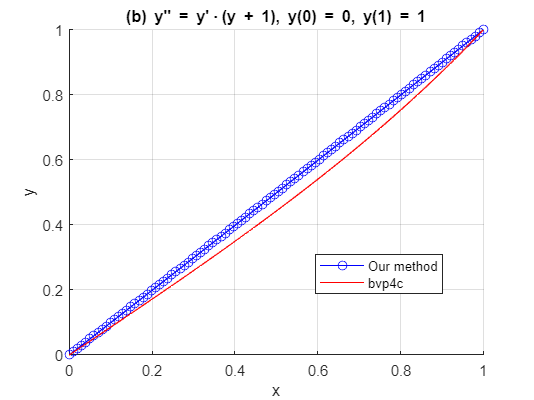

figure; hold on; grid on;
plot(x, U, 'b-o', x, U_ref(1, :), 'r-');
title("(b) y'' = y'\cdot(y + 1), y(0) = 0, y(1) = 1");
legend('Our method', 'bvp4c', 'Location', 'best');
xlabel('x'); ylabel('y');
hold off;

# **Problema 4**

(a) Determinati o formula de cuadratura de tip Gauss de forma $\int_{-\infty }^{\infty } \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }f\left(t\right)\mathrm{dt}=A_1 f\left(t_1 \right)+A_2 f\left(t_2 \right)+R\left(f\right)$care sa aiba grad maxim de exactitate.

Cuadraturile de tip Gauss au gradul maxim de exactitate $d=2n-1$. Avem $n=2$ noduri, rezulta gradul maxim de exactitate $d=2*2-1=3$, adica formula de cuadratura trebuie sa fie exacta pentru polinoame pana la grad 3, inclusiv.

Intervalul de integrare si forma functiei ponderilor $\omega \left(t\right)=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }$ nu corespund niciunui polinom ortogonal clasic, astfel ca trebuie sa construim de la 0 formula de cuadratura. Vom folosi metoda momentelor pentru a determina coeficientii si nodurile:$\mu_k =\int_{-\infty }^{\infty } t^k \omega \left(t\right)\mathrm{dt},\omega \left(t\right)=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }$. Se observa ca functia ponderilor este **para**: $\omega \left(t\right)=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }=\frac{1}{e^t {\left(1+\frac{1}{e^t }\right)}^2 }=\frac{1}{e^t \cdot \frac{{\left(e^t +1\right)}^2 }{e^{2t} }}=\frac{e^t }{\left(1+e^t \right)}=\omega \left(-t\right)$. Pentru integralele definite pe intervale simetrice, functiile impare au valoarea 0, deoarece aceste se anuleaza in punctele aflate la distante egale de axa Ox. Astfel, integrala momentelor va avea valoarea $t^k \omega \left(t\right)=\left\lbrace \begin{array}{ll}
0 & k-\mathrm{impar}\\
\int_{-\infty }^{\infty } t^k \cdot \omega \left(-t\right)\mathrm{dt} & k-\mathrm{par}
\end{array}\right.$.


$$\begin{array}{l}
A_1 +A_2 =\int_{-\infty }^{\infty } t^0 \cdot \omega \left(t\right)\mathrm{dt}=1\\
A_1 t_1 +A_2 t_2 =0\\
A_1 t_1^2 +A_2 t_2^2 =\int_{-\infty }^{\infty } \frac{{t^2 e}^t }{{\left(1+e^t \right)}^2 }\mathrm{dt}=\frac{\pi^2 }{3}\\
A_1 t_1^3 +A_2 t_2^3 =0
\end{array}$$


Rezulta solutiile:


$$A_1 =\left(\frac{1}{2},\frac{1}{2}\right),A_2 =\left(\frac{1}{2},\frac{1}{2}\right),t_1 =\left(-\frac{\pi \sqrt{3}}{3},\frac{\pi \sqrt{3}}{3}\right),t_2 =\left(\frac{\pi \sqrt{3}}{3},-\frac{\pi \sqrt{3}}{3}\right)$$



$$t_{1,2} \approx \pm 1\ldotp 813799364$$


Valorile nodurilor sunt simetrice, valorile coeficientilor sunt aceleasi, rezulta astfel ca avem doar o solutie unica pentru formula noastra.

Restul se va estima folosind formula:

$R\left(f\right)=\frac{f^{\left(2n\right)} \left(\xi \right)}{\left(2n\right)!}\cdot \int_{-\infty }^{\infty } {\left\lbrack \pi_n \left(t\right)\right\rbrack }^2 \omega \left(t\right)\textrm{dt}-\xi \in \left(-\infty ,\infty \right)$, unde $\pi_n \left(t\right)$este polinomul ortogonal de grad n fata de $\omega \left(t\right)$. Polinomul nostru ortogonal de grad 2 este $\pi_2 \left(t\right)=t^2 -\frac{1}{2}$, extras din valorile radacinilor.

Restul este: $R\left(f\right)=\frac{f^{\left(4\right)} \left(\xi \right)}{4!}\int_{-\infty }^{\infty } {\left(t^2 -\frac{\sqrt{\pi }}{3}\right)}^2 \cdot \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }\mathrm{dt},\xi \in \left(-\infty ,\infty \right)$.

Formula de cuadratura rezultata este:


$$\int_{-\infty }^{\infty } \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }f\left(t\right)\mathrm{dt}=\frac{1}{2}f\left(-\frac{\pi \sqrt{3}}{3}\right)+\frac{1}{2}f\left(\frac{\pi \sqrt{3}}{3}\right)+\frac{f^{\left(4\right)} \left(\xi \right)}{4!}\int_{-\infty }^{\infty } {\left(t^2 -\frac{\sqrt{\pi }}{3}\right)}^2 \cdot \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }\mathrm{dt},\xi \in \left(-\infty ,\infty \right)$$


Functia de pondere este prost instabila numeric pentru valori mari ale lui t, dupa cum se poate observa in graficul de mai jos. Pentru aproximativ$|t|\ge 6$, valorile functiei de ponderare sunt nule, din cauza aceasta aparand si problemele. Vom stabili astfel ca integrala sa fie calculata pe un interval trunchiat, pentru a exclude problema anularii.

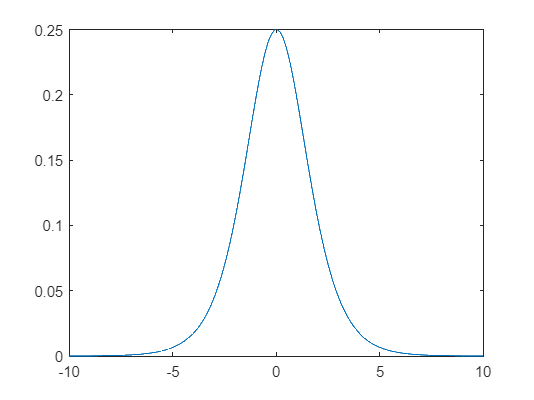

w = @(t) exp(t) ./ ((1 + exp(t)).^2);
tt = linspace(-10, 10, 10000);
plot(tt, w(tt));

(b) Aproximati integrala


$$\int_{-\infty }^{\infty } \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }\left(x+\mathrm{cosx}+1\right)\mathrm{dt}$$


cu 6 zecimale exacte corecte folosind o cuadratura de tip Laguerre.

Nici intervalul de integrare, nici ponderea nu au forme standard Laguerre. Observam ca functia de ponderare $\omega \left(t\right)=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }=\sigma^{\prime } \left(t\right)$. Spargem integrala in doua pentru a putea defini o cuadratura Laguerre:

$\left(x+\mathrm{cosx}+1\right)\int_{-\infty }^{\infty } \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }\mathrm{dt}=\left(x+\mathrm{cosx}+1\right)\left(\int_{-\infty }^0 \sigma^{\prime } \left(-t\right)\mathrm{dt}+\int_0^{\infty } \sigma^{\prime } \left(t\right)\mathrm{dt}\right)$, dar $\sigma^{\prime } \left(t\right)$ este o functie para, asa ca integrala noastra devine $2\left(x+\mathrm{cosx}+1\right)\cdot \int_0^{\infty } \sigma^{\prime } \left(t\right)\mathrm{dt}=2\left(x+\mathrm{cosx}+1\right)\cdot \int_0^{\infty } e^{-t} \cdot \frac{1}{{\left(1+e^{-t} \right)}^2 }\mathrm{dt},f\left(t\right)=\frac{1}{{\left(1+e^{-t} \right)}^2 }$

Putem calcula $\int_0^{\infty } e^{-t} \cdot \frac{1}{{\left(1+e^{-t} \right)}^2 }\mathrm{dt}$ folosind o cuadratura de tip Laguerre.

## a) Verificarea formulei de cuadratura rezultata

A1 = 1/2;
A2 = 1/2;
t1 = -pi * sqrt(3) / 3;
t2 = pi * sqrt(3) / 3;

% Functia de test
f = @(x) exp(x);

% Functia ponderilor
w = @(t) exp(t) ./ ((1 + exp(t)).^2);

% Integrala aproximata
I_approx = A1 * f(t1) + A2 * f(t2);

% Integrala exacta
I = @(t) w(t) .* f(t);
I_exact = integral(I, -100, 100);
err_real = abs(I_exact - I_approx);
% Eroarea (teoretic)
f4 = @(x) exp(x);
xi = 0;
f4xi = f4(xi);

err_w = @(t) w(t) .* (t.^2 - sqrt(pi)/3) .^ 2;
C = integral(err_w, -100, 100);
err_th = (f4xi / factorial(4)) * C;

fprintf("Aproximarea cu formula de cuadratura: %g\n", I_approx);

Aproximarea cu formula de cuadratura: 3.14837


fprintf("Valoarea exacta a integralei: %g\n", I_exact);

Valoarea exacta a integralei: 99


fprintf("Eroarea absoluta (REAL): %g\n", err_real);

Eroarea absoluta (REAL): 95.8516


fprintf("Eroarea absoluta (TEORETIC): %g\n", err_th);

Eroarea absoluta (TEORETIC): 1.74663


## b) integrala cu cuadratura de tip Laguerre

% functia constanta x + cos(x) + 1 cu x ales arbitrar
x = 1;
f_const = @(x) x + cos(x) + 1;

f = @(t) 1 ./ (1+ exp(-t)).^2;

max_iter = 100;
tol = 1e-6;
n = 2;

I_half_ref = integral(@(t) exp(-t) .* f(t), 0, Inf);
I_exact = 2 * f_const(x) * I_half_ref;

for iter = 1:max_iter
    [g_nodes, g_coeffs] = gauss_laguerre(n, 0);  % cuadratură standard
    I_approx = 2 * f_const(x) * sum(g_coeffs(:) .* f(g_nodes(:)));

    fprintf("n = %d | Aproximare: %.10f\n", n, I_approx)

    if abs(I_approx - I_exact) < tol
        fprintf("Toleranta %g atinsa in %d iteratii!\n", tol, iter);
        fprintf("Exact: %.16g | Approx: %.16g\n", I_exact, I_approx);
        break
    end
    n = n + 1;
end

n = 2 | Aproximare: 2.4869833486
n = 3 | Aproximare: 2.5316099612
n = 4 | Aproximare: 2.5431823027
n = 5 | Aproximare: 2.5419749948
n = 6 | Aproximare: 2.5405465237
n = 7 | Aproximare: 2.5401621293
n = 8 | Aproximare: 2.5401878666
n = 9 | Aproximare: 2.5402618683
n = 10 | Aproximare: 2.5402999654
n = 11 | Aproximare: 2.5403096479
n = 12 | Aproximare: 2.5403082368
n = 13 | Aproximare: 2.5403050490
n = 14 | Aproximare: 2.5403029617


Toleranta 1e-06 atinsa in 13 iteratii!


Exact: 2.54030230586814 | Approx: 2.540302961717308


if iter >= max_iter
    error("Nu s-a atins convergenta in %d maximum iteratii!", max_iter);
end

function [U, iter] = solve_bvp_newton(n, a, b, alpha, beta, tol, max_iter)
    %% SOLVE_BVP_NEWTON - rezolvarea unei probleme cu valori pe frontiera, in forma discretizata,
    %                     folosind o metoda bazata pe metoda lui Newton
    % Inputs:
    %
    % n         - numarul de puncte;
    % a, b      - domeniul de definitie;
    % alpha     - valoarea la stanga frontierei. Default: a;
    % beta      - valoarea la dreapta frontierei. Default: b.
    % tol       - toleranta = eroarea intre 2 iteratii considerata acceptabila. Default: 1e-6;
    % max_iter  - numarul maxim de iteratii. Default: 100;
    %
    % Outputs:
    %
    % U         - solutiile;
    % iter      - numarul de iteratii pana la convergenta;
    %%
    if n < 0 || floor(n) ~= n
        error('%g trebuie sa fie intreg pozitiv')
    end

    if b <= a
        error('Domeniu de definitie [%g, %g] invalid!', a, b);
    end

    if nargin < 4
        alpha = a;
    end
    if nargin < 5
        beta = b;
    end
    if nargin < 6
        tol = 1e-6;
    end
    if nargin < 7
        max_iter = 100;
    end

    % Pasul dintre punctele echidistante
    h = (b-a) / ((n+1)^2);

    % Solutiile initiale, pastrand doar necunoscutele u1,...,un
    u = linspace(alpha, beta, n+2);
    u = u(2:end-1)';

    for i = 1:max_iter
        % Functia vectoriala si Jacobianul
        F = zeros(n, 1);
        J = zeros(n, n);

        % Vectorul solutiilor extins (cu conditiile de frontiera)
        uext = [alpha; u; beta];

        % Construim functia vectoriala si Jacobianul
        for k = 1:n
            ukm1 = uext(k);     % u_{k-1}
            uk = uext(k+1);     % u_k
            ukp1 = uext(k+2);   % u_{k+1}

            % Valorile derivatelor
            du1 = (ukp1 - ukm1) / (2 * h);
            du2 = (ukp1 - 2 * uk + ukm1) / (h ^ 2);

            F(k) = du2 - du1 .* (uk + 1);

            % Elementele Jacobianului
            if k > 1
                J(k, k-1) = (1 / h^2) + (uk / (2 * h));
            end
            J(k, k) = (-2 / h^2) - du1;
            if k < n
                J(k, k+1) = (1 / h^2) - (uk / (2 * h));
            end
        end

        % Pasul din iteratia Newton
        delta = J \ F;
        u = u - delta;

        if norm(delta, inf) < tol
            fprintf('Convergenta atinsa in %d iteratii!', i);
            U = [alpha; u; beta]';
            if nargout == 2
                iter = i;
            end
            return;
        end
    end

    error('Convergenta nu a fost atinsa in %d iteratii!', max_iter);
end

function [g_nodes, g_coeff] = gauss_quad(alpha, beta)
    %% GAUSS_QUAD - generare cuadratura Gauss
    %               calculeaza noduri si coeficienti pentru cuadraturi
    %               Gauss, cu alpha si beta cunoscuti, folosing matricea
    %               Jacobi
    %
    %   Inputs:
    %   
    %   - alpha, beta   - coeficientii cunoscuti pentru matricea Jacobi
    %
    %   Outputs:
    %
    %   - g_nodes       - nodurile cuadraturii Gauss;
    %   - g_coeff       - coeficientii cuadraturii Gauss;

    % Numarul de noduri
    n = length(alpha);

    % Radacinile elementelor Beta ale termenilor sub/supra-diagonali
    rb = sqrt(beta(2:n));

    % Matricea Jacobi - matrice tridiagonala
    J = diag(alpha) + diag(rb, -1) + diag(rb, 1);

    % Diagonalizarea lui J - d va contine valorile_proprii/nodurile
    [v, d] = eig(J);

    % Nodurile cuadraturii
    g_nodes = diag(d);

    % Coeficientii cuadraturii - patratul primei componente din vectorul
    % propriu
    g_coeff = beta(1) * v(1, :) .^ 2;
end

function [g_nodes, g_coeff] = gauss_laguerre(n, a)
    %% GAUSS_LAGUERRE - determina coeficientii si nodurile pentru o cuadratura de tip Gauss-Laguerre
    %
    %   Inputs:
    %   
    %   - n     - numarul de noduri;
    %   - a     - parametru de ponderare, > -1

    % Coeficientii Jacobi
    k = 0:n-1;
    alpha = 2*k + a + 1;          % diagonala
    beta = [1, k(2:end) .* (k(2:end) + a)];  % sub/super-diagonala

    [g_nodes, g_coeff] = gauss_quad(alpha', beta');
end